clear all

save_dir_sos = append(pwd,"\controller_K0_SOS_ZPK.mat");
save_dir_fig = pwd;
folder_name = save_dir_fig;
%Physical constants for implementation. First simulation will be for mu \leq 0. 
%After, with K0 will propose some coefficients that improves perfomance
%based on reward function. PPO will find those coefficients
w = 2;
beta = 0.5;
mu_design = -0.5;
mu_target = 3;
%%%Initial Conditions (IC)
x0 = [0.6;0.1];
dt = 2e-2; %Just for figure sampling in simulink
Ts = 2e-2;
A = [mu_design -w; 
     w  mu_design];
B = [1;0];
C = [0,1]; %Just x measure
D = zeros(size(C,1),1);
syslin = ss(A,B,C,D,name ='Linear Model: Stuart Landau');
%%%K0 LQG TO STABILISE MU_DESIGN
K0_lqg = K0_lqg_synth(mu_design,w);
K0_zpk = K0_sos2zpk(K0_lqg,Ts,'ss',save_dir_sos);
%%%Discrete system to simulate ZPK
A_K0 = K0_zpk.Ad_sos;
B_K0 = K0_zpk.Bd_sos;
C_K0 = K0_zpk.Cd_sos;
D_K0 = K0_zpk.Dd_sos;
K0_disc = ss(A_K0,B_K0,C_K0,D_K0,Ts,name='K0: mu_design discrete controller');

%%% LOAD FINAL CONTROLLER FROM PYTHON FOR POSTPROCESSING %%%
KPPO_FINAL = load("stuart_landau_final_controller_KPPO.mat");
%%%ZPK FINAL SECTION AFTER PPO: PYTHON
Kg_ppo = KPPO_FINAL.Kg_final

Kg_ppo = -18.7996

P_ppo = KPPO_FINAL.P_sections_final;
Z_ppo = KPPO_FINAL.Z_sections_final(~isnan(KPPO_FINAL.Z_sections_final));
%%%DISCRETE SYSTEM PPO HYBRID - ZPK FOR SIMULINK SIMULATION
tf_ppo = zpk(Z_ppo,P_ppo,Kg_ppo,Ts);
[A_KPPO,B_KPPO,C_KPPO,D_KPPO] = zp2ss(Z_ppo,P_ppo,Kg_ppo);

%%%LOAD PYTHON DATA%%%
PYTHON_MU_TARGET_K0_csv = readtable("stuart_landau_initial_closed_loop_K0_signals.csv",VariableNamingRule='preserve');
PYTHON_MU_TARGET_KPPO_csv = readtable("stuart_landau_final_closed_loop_KPPO_signals.csv",VariableNamingRule='preserve');

%%%EXTRACTING DATA FROM SIMULINK/PYTHON (COMPARISON CLOSED-LOOP K0+PPO)
%%%CLOSED-LOOP DATA: K0 FOR MU_DESIGN
Tsim_MU_TARGET_K0 = out.STUART_LANDAU_MU_TARGET_K0.Time;
Y_MU_TARGET_K0 = out.STUART_LANDAU_MU_TARGET_K0.Data(:,1); 
F_raw_MU_TARGET_K0 = out.STUART_LANDAU_MU_TARGET_K0.Data(:,2);
F_sat_MU_TARGET_K0 = out.STUART_LANDAU_MU_TARGET_K0.Data(:,3);                                                                                     
%%%CLOSED-LOOP DATA: K0+PPO FOR MU_TARGET
Tsim_MU_TARGET_KPPO = out.STUART_LANDAU_MU_TARGET_KPPO.Time;
Y_MU_TARGET_KPPO = out.STUART_LANDAU_MU_TARGET_KPPO.Data(:,1); 
F_raw_MU_TARGET_KPPO = out.STUART_LANDAU_MU_TARGET_KPPO.Data(:,2);
F_sat_MU_TARGET_KPPO = out.STUART_LANDAU_MU_TARGET_KPPO.Data(:,3);
%%%CLOSED-LOOP DATA: K0 FOR MU_DESIGN PYTHON
PY_Tsim_MU_TARGET_K0 = PYTHON_MU_TARGET_K0_csv.t;
PY_Y_MU_TARGET_K0 = PYTHON_MU_TARGET_K0_csv.y_0;
PY_F_raw_MU_TARGET_K0 = PYTHON_MU_TARGET_K0_csv.u_raw_0;
PY_F_sat_MU_TARGET_K0 = PYTHON_MU_TARGET_K0_csv.u_sat_0;
%%%%CLOSED-LOOP DATA: KPPO FOR MU_TARGET PYTHON
PY_Tsim_MU_TARGET_KPPO = PYTHON_MU_TARGET_KPPO_csv.t;
PY_Y_MU_TARGET_KPPO = PYTHON_MU_TARGET_KPPO_csv.y_0;
PY_F_raw_MU_TARGET_KPPO = PYTHON_MU_TARGET_KPPO_csv.u_raw_0;
PY_F_sat_MU_TARGET_KPPO = PYTHON_MU_TARGET_KPPO_csv.u_sat_0;

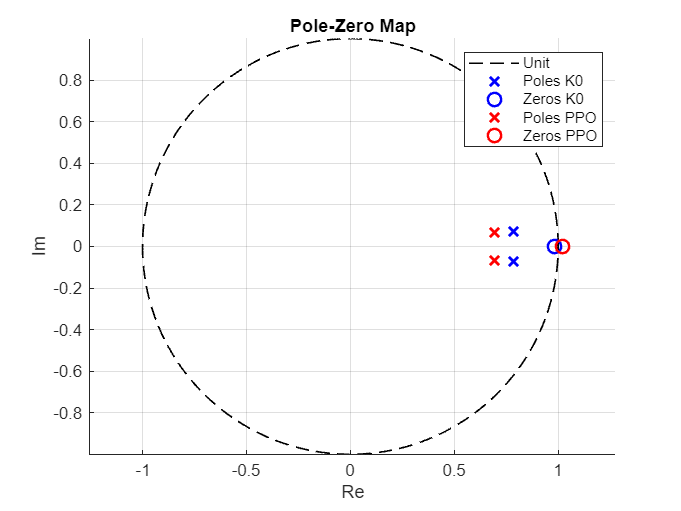

clf
hold on
grid on
ms = 8;
[p1, z1] = pzmap(K0_disc);
[p3, z3] = pzmap(tf_ppo);
theta = linspace(0, 2*pi, 500);
plot(cos(theta), sin(theta), 'k--', 'LineWidth', 1)
plot(real(p1), imag(p1), 'xb', 'MarkerSize', ms, 'LineWidth', 1.5)
plot(real(z1), imag(z1), 'ob', 'MarkerSize', ms, 'LineWidth', 1.5)
plot(real(p3), imag(p3), 'xr', 'MarkerSize', ms, 'LineWidth', 1.5)
plot(real(z3), imag(z3), 'or', 'MarkerSize', ms, 'LineWidth', 1.5)
xlabel('Re')
ylabel('Im')
axis equal
legend('Unit','Poles K0', 'Zeros K0','Poles PPO', 'Zeros PPO')
title('Pole-Zero Map');
hold off

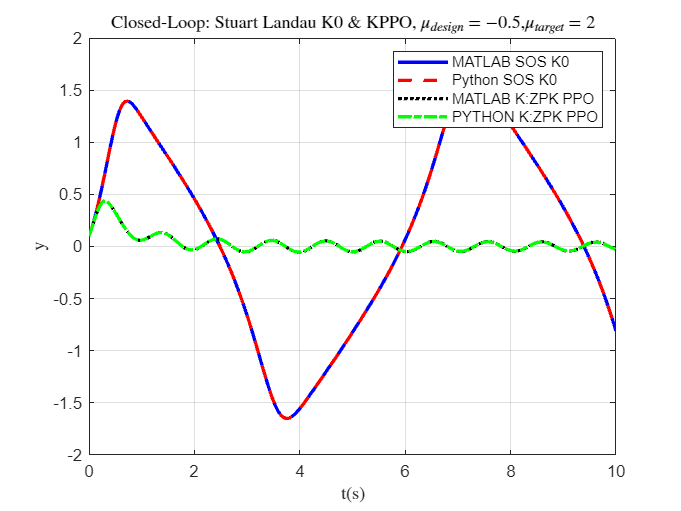

clf
%%%COMPARISON PLOTS : DISCRETE DYNAMICS
plot(Tsim_MU_TARGET_K0,Y_MU_TARGET_K0,Color="b",LineWidth=2)
title('Closed-Loop: Stuart Landau K0 \& KPPO, $\mu_{design}=-0.5$,$\mu_{target}=2$','Interpreter', 'latex')
xlabel('t(s)', Interpreter='latex')
ylabel('y', Interpreter="latex")
hold on 
plot(PY_Tsim_MU_TARGET_K0,PY_Y_MU_TARGET_K0,Color="r",LineWidth=2,LineStyle="--")
plot(Tsim_MU_TARGET_KPPO,Y_MU_TARGET_KPPO,Color="k",LineWidth=2,LineStyle=":")
plot(PY_Tsim_MU_TARGET_KPPO,PY_Y_MU_TARGET_KPPO,Color="g",LineWidth=2,LineStyle="-.")
grid on
legend({'MATLAB SOS K0','Python SOS K0','MATLAB K:ZPK PPO','PYTHON K:ZPK PPO'})
xlim([0 Tsim_MU_TARGET_K0(end)])
hold off
%%%SAVE IMAGE 
filename = fullfile(folder_name, 'stuart_landau_closed_loop_Hybrid_K0_KPPO.png');
exportgraphics(gcf, filename, 'Resolution', 300)

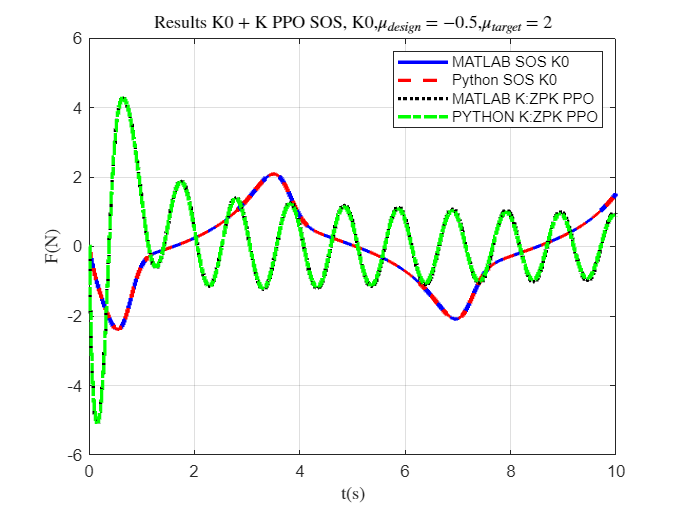

clf
%%COMPARISON PLOTS
stairs(Tsim_MU_TARGET_K0,F_sat_MU_TARGET_K0,Color="b",LineWidth=2)
xlabel('t(s)', Interpreter='latex')
ylabel("F(N)", Interpreter="latex")
hold on 
stairs(PY_Tsim_MU_TARGET_K0,PY_F_sat_MU_TARGET_K0,Color="r",LineWidth=2,LineStyle="--")
stairs(Tsim_MU_TARGET_KPPO,F_sat_MU_TARGET_KPPO,Color="k",LineWidth=2,LineStyle=":")
stairs(PY_Tsim_MU_TARGET_KPPO,PY_F_sat_MU_TARGET_KPPO,Color="g",LineWidth=2,LineStyle="-.")
grid on
legend({'MATLAB SOS K0','Python SOS K0','MATLAB K:ZPK PPO','PYTHON K:ZPK PPO'})
xlim([0 Tsim_MU_TARGET_K0(end)])
hold off
title(' Results K0 + K PPO SOS, K0,$\mu_{design}=-0.5$,$\mu_{target}=2$','Interpreter', 'latex')
%%%SAVE IMAGE 
filename = fullfile(folder_name, 'stuart_landau_closed_loop_SatForce_K0_KPPO.png');
exportgraphics(gcf, filename, 'Resolution', 300)